# Узкополосная частотная модуляция 

# Narrow Band Frequency Modulation

# (NBFM)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

В FM Transitter Basics были рассмотрены оснывные принципы частотной модуляции и введены такие важные понятия как девиация и индекс модуляции. Было показано, что при малых индексах модуляции спектр сигнала состоит из несущей и бововых полос и чем-то напоминает спектр АМ-сигнала. Такое случай называется узкополосной частотной модуляцией (Narrow Band Frequency Modulation - NBFM). Рассмотрим NBFM подробнее.

### 2. Однотональная модуляция

Начнем с наиболее простого случая однотональной модуляции.Информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Напомним, что в общем виде частотно-модулированный сигнал можно записать в виде:

 
$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\;\;\;\;\;\;\;\;\left(1\right),$$


где $A_с$ - амплитуда несущей, $f_с$ - частота несущей, $K_f$ - чувствительность модулятора.

Подставим это выражение в уравнение для однотонального сообщения в (3) и получим:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t A_m \cos \left(2\pi f_m t\right)\cdot d\tau \right)\ldotp$$


После интегрирования получим:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+\frac{2\pi K_f A_m }{2\pi f_m }\cdot \sin \left(2\pi f_m t\right)\right)=A_с \cdot \cos \left(2\pi f_с t+\frac{K_f A_m }{f_m }\cdot \sin \left(2\pi f_m t\right)\right)=A_с \cdot \cos \left(2\pi f_с t+\beta \cdot \sin \left(2\pi f_m t\right)\right),$$


где $\beta =\frac{K_f A_m }{f_m }$ - индекс модуляции.

Применим к найденному уравнению формулу суммы углов для косинуса. Тогда модулированный сигнал примет вид:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+\beta \cdot \sin \left(2\pi f_m t\right)\right)=A_с \cdot \cos \left(2\pi f_с t\right)\cdot \cos \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)-A_с \cdot \sin \left(2\pi f_с t\right)\cdot \sin \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)\ldotp$$


Далее воспользуемся условием, что модуляция узкополосная, то есть, $\beta <<1$. Так как значение синуса и косинуса ограничено диапазоном от -1 до 1, это означает, что величина $\left|\beta \cdot \sin \left(2\pi f_m t\right)\right|<<1$. Это позволяет нам воспользоваться аппроксимацией при $x<<1$: $\cos \left(x\right)\approx 1$ и $\sin \left(x\right)\approx x$. Тогда уравнение для узкополосного сигнала упростится:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t\right)\cdot 1-A_с \cdot \sin \left(2\pi f_с t\right)\cdot \beta \cdot \sin \left(2\pi f_m t\right)\ldotp$$


Наконец, воспользуемся формулой произведения синусов и получим окончательный результат.


$$s\left(t\right)=A_с \cdot \left\lbrack \cos \left(2\pi f_с t\right)+\frac{\beta }{2}\cos \left(2\pi \left(f_с +f_m \right)t\right)-\frac{\beta }{2}\cos \left(2\pi \left(f_с -f_m \right)t\right)\right\rbrack \ldotp$$


Таким образом, при однотональной узкополосной частотной модуляции сигнал будет состоять из трех гармоник: несущей и двух боковых тонов на частотах $f_с +f_m$ и $f_с -f_m$. Именно этот результат был получен в FM Transitter Basics при однотональной модуляции с низким значением $\beta$.

Рассмотрим теперь общий случай NBFM сигнала, который описывается формулой (1). Применим к нему правило суммы углов косинуса и получим:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)=\;\;\;\;\;\;\;$$



$$=A_с \cdot \left\lbrack \cos \left(2\pi f_с t\right)\cdot \cos \left(2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)-\sin \left(2\pi f_с t\right)\cdot \sin \left(2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\right\rbrack \ldotp$$


Заметим, что чувствительность приемника связана с индексом модуляции следующим соотношением:


$$\beta =\frac{\Delta f}{f_m }=\frac{K_f \cdot \max \left|m\left(t\right)\right|}{f_m },$$


где $f_m$ - максимальная частота в спектре информационного сообщения, $\max \left|m\left(t\right)\right|$ - максимальная амплитуда информационного сообщения, $\Delta f$ - девиация. Выразим $K_f$ и получим:


$$K_f =\beta \cdot \frac{f_m }{\max \left|m\left(t\right)\right|}\ldotp$$


То есть, при заданном информационном сообщении значения $\max \left|m\left(t\right)\right|$ и $f_m$ являются константами, и чувствительность модулятора $K_f$ прямо пропрорциональна индексу модуляции $\beta$. Уменьшая $\beta$, мы уменьшаем значение $K_f$, а значит и величину произведения  $2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau$. При достаточно низких значениях $\beta$ мы получим, что 


$$\left|2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right|<<1\ldotp$$


Тогда мы можем воспользоваться аппроксимацией малых углов для синуса и косинуса:


$$s\left(t\right)=A_с \cdot \left\lbrack \cos \left(2\pi f_с t\right)\cdot \cos \left(2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)-\sin \left(2\pi f_с t\right)\cdot \sin \left(2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\right\rbrack =$$



$$=A_с \cdot \left\lbrack \cos \left(2\pi f_с t\right)-\sin \left(2\pi f_с t\right)\cdot 2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right\rbrack \ldotp$$


Отсюда видно, как формируется NBFM сигнал. Он состоит из произведения интеграла от информационного сообщения и несущей ($\sin \left(2\pi f_с t\right)$), к которому добавляется несущая сдвинутая по фазе на 90 градусов ($\cos \left(2\pi f_с t\right)$). В результате получим, что сигнал будет состоят из тона на частоте несущей $A_с \cdot \cos \left(2\pi f_с t\right)$, и двух боковых полос с интегралом от информационного сигнала: $\sin \left(2\pi f_с t\right)\cdot 2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau$.

Это также позволяет предложить схему узкополосного частотного модулятора:

### 2. Однотональная узкополосная модуляция

Рассмотрим схему узкополосного частотного модулятора на примере однотонального сообщения. Скрипт, реализующий модулятор и позволяющий увидеть спектр сигнала представлен ниже:

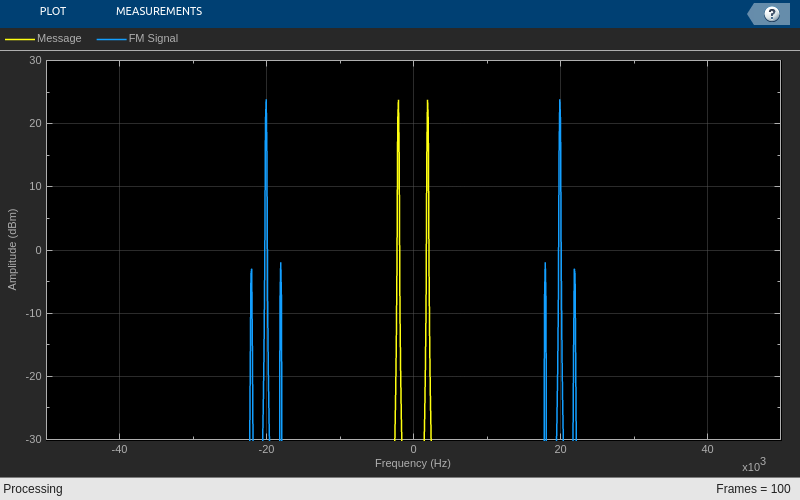

clc; clear; close all;

FrameSize = 1011;       % размер обрабатываемой за один раз пачки данных
Fs = 100e3;             % частота дискретизации (Hz)
Fc = 20e3;              % частота несущей (Hz)
Am = 1;                 % амплитуда тонального сообщения
Fm = 2e3;               % частота тонального сообщения (Hz)
ModIndex = 0.1;         % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', [Fc Fc],...
    'Amplitude', [1 1], ...
    'PhaseOffset', [0 pi/2] ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% начальное значение интегратора
AccumInitValue = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();
    
    % интегрирование сообщения
    MessageIntegral = AccumInitValue + 1/Fs * cumsum(MessageData);
    
    % обновление начального значения интегратора
    AccumInitValue = MessageIntegral(end);

    % получание несущей
    CarrierWave = Carrier();
    SinWave = CarrierWave(:,1);
    CosWave = CarrierWave(:,2);

    % умножение на несущую и добавление несущей сдвинутой по фазу
    FmSignal = CosWave - 2*pi*Kf * SinWave.*MessageIntegral; 
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, FmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

 На спектрограмме можно увидеть, что модулированный сигнал действительно состоит их несущей и двух боковых тонов.

### 3. Коррекция побочной амплитудной модуляции

Так как в узкополосном частотном модуляторе используется аппроксимация гармонических функций при условии малого угла, полученный сигнал будет иметь некоторые искажения. Например, ампитуда сигнала может не быть строго постоянной, а в сигнале будет присутствовать побочная амплитудная модуляция. Причем, чем сильнее будет расхождение между предположением о малом угле в гармочиеских функциях и реальными значениями, тем хуже будет выполняться аппроксимация, и тем сильнее будет проявляться побочная амплитудная модуляция.

Ниже представлен скрипт, выполняющий узкополосную модуляцию однотональным сигналом с индексом модуляции, равным 0.5.

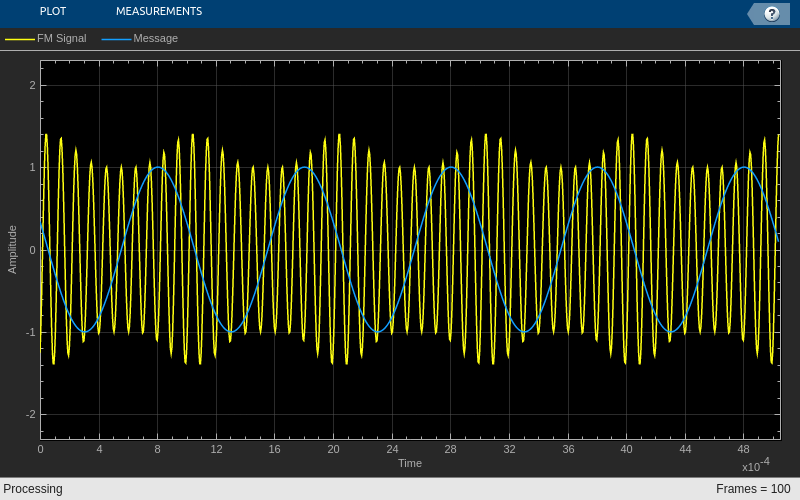

clc; clear; close all;

FrameSize = 1011;       % размер обрабатываемой за один раз пачки данных
Fs = 200e3;             % частота дискретизации (Hz)
Fc = 10e3;              % частота несущей (Hz)
Am = 1;                 % амплитуда тонального сообщения
Fm = 1e3;               % частота тонального сообщения (Hz)
ModIndex = 0.5;         % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', [Fc Fc],...
    'Amplitude', [1 1], ...
    'PhaseOffset', [0 pi/2] ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );

% начальное значение интегратора
AccumInitValue = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();
    
    % интегрирование сообщения
    MessageIntegral = AccumInitValue + 1/Fs * cumsum(MessageData);
    
    % обновление начального значения интегратора
    AccumInitValue = MessageIntegral(end);

    % получание несущей
    CarrierWave = Carrier();
    SinWave = CarrierWave(:,1);
    CosWave = CarrierWave(:,2);

    % умножение на несущую и добавление несущей сдвинутой по фазу
    FmSignal = CosWave - 2*pi*Kf * SinWave.*MessageIntegral; 
    
    % вывод результатов на график
    Plotter([FmSignal, MessageData])
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На временной диаграмме можно явно увидеть побочную амплитудную модуляцию у сформированного сигнала. Непостоянство амплитуды сигнала может вносить искажения в восстановленное сообщения при демодуляции, поэтому с этим явлением нужно бороться. 

Один из способов решения данной проблемы заключается в использовании ограничителя и полосового фильтра после получения модулированного сигнала. Рассмотрим, как этом работает. Запишим еще рах, как выглядит частотно-модулированный сигнал в общем виде:


$$s\left(t\right)=A\left(t\right)\cdot \mathrm{cos}\left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)=A\left(t\right)\cdot \mathrm{cos}\left(\theta \left(t\right)\right),$$


где $A\left(t\right)$ - изменяющаяся со временем из-за побочной модуляции амплитуда сигнала.

Пропустим данный сигнал, через огриничитель (limiter), принцип работы которого описывается следующим выражением:

$s_{\mathrm{lim}} \left(t\right)=\left\lbrace \begin{array}{cc}
1 & \mathrm{при}\;s\left(t\right)>0\\
-1 & \mathrm{при}\;s\left(t\right)<0
\end{array}\right.$.

То есть, выходной  сигнал будет равен единице, если входной сигнал больше нуля, и минус единице, если входной сигнал отрицательный. Амплитуда сигнала всегда $A\left(t\right)$ больше нуля, поэтому выход ограничителя будет зависеть только от знака косинуса. Можем переписать уравнение ограничителя в виде:

$s_{\mathrm{lim}} \left(t\right)=\left\lbrace \begin{array}{cc}
1 & \mathrm{при}\;\mathrm{cos}\left(\theta \left(t\right)\right)>0\\
-1 & \mathrm{при}\;\mathrm{cos}\left(\theta \left(t\right)\right)<0
\end{array}\right.$.

Таким образом, на выходе ограничителя получим прямоугольный сигнал, амплитуда которого равна 1 или -1, и частота которого совпадает с частотой модулированного сигнала. Если разложить данный прямоугольный сигнал в ряд Тейлора, то получим:

$s_{\mathrm{lim}} \left(t\right)=\frac{4}{\pi }\cdot \left(\mathrm{cos}\left(\theta \left(t\right)\right)-\frac{1}{3}\mathrm{cos}\left(3\cdot \theta \left(t\right)\right)+\frac{1}{5}\mathrm{cos}\left(5\cdot \theta \left(t\right)\right)+\ldotp \ldotp \ldotp \right)$,

где $\theta \left(t\right)=2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau$.

Отсюда видим, что выход ограничителя будет состоять из суммы множества частотно-модулированных сигналов, амплитуды которых постоянны. Из этой суммы нам требуется только первое слагаемое, которые можно выделить с помощью полосового фильтра. Сигнал на выходе фильтра будет иметь вид:

 
$$s_{\mathrm{fllter}} \left(t\right)=\frac{4}{\pi }\cdot \mathrm{cos}\left(\theta \left(t\right)\right)=\frac{4}{\pi }\cdot \mathrm{cos}\left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\ldotp$$


Таким образом, мы смогли избавиться от побочной амплитудной модуляции. Скрипт, выполняющий описанные ранее преобразования представлен ниже:

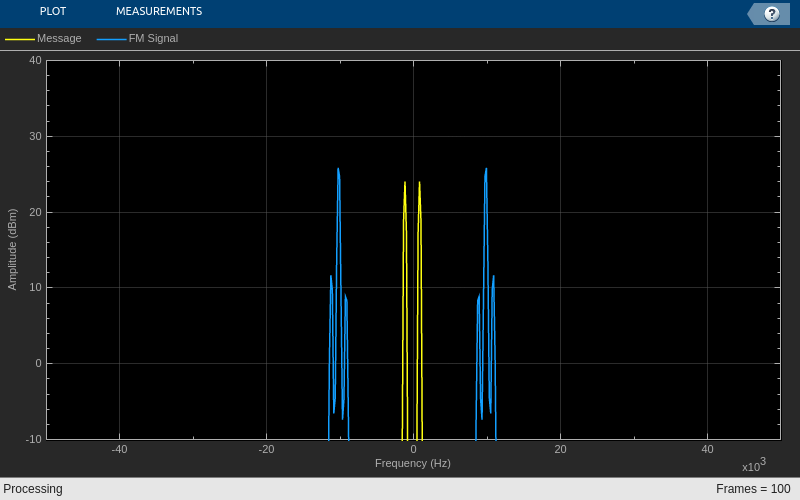

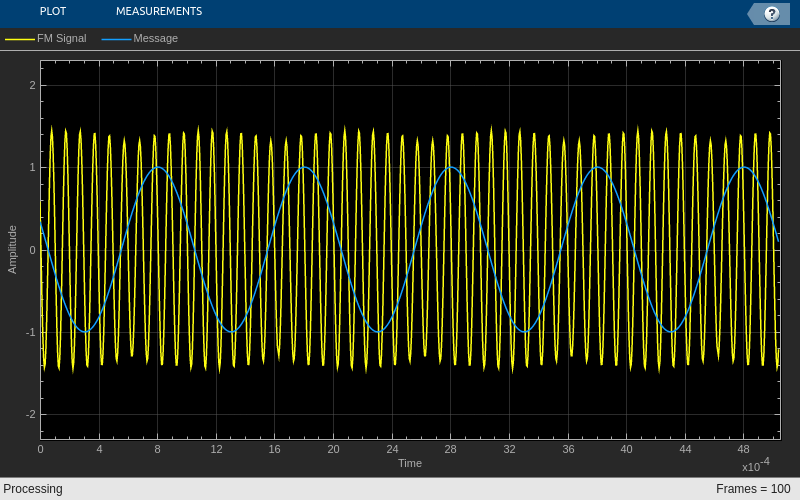

clc; clear; close all;
addpath('matlab/modulation');

FrameSize = 1011;       % размер обрабатываемой за один раз пачки данных
Fs = 200e3;             % частота дискретизации (Hz)
Fc = 10e3;              % частота несущей (Hz)
Am = 1;                 % амплитуда тонального сообщения
Fm = 1e3;               % частота тонального сообщения (Hz)
ModIndex = 0.5;         % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', [Fc Fc],...
    'Amplitude', [1 1], ...
    'PhaseOffset', [0 pi/2] ...
    );

% расчет коэффициентов полосового фильтра
H = Limiter_Bandpass_Filter_Tone(); 
BandpassFIR = dsp.FIRFilter(H.Numerator);

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объекты для отрисовки графиков
PlotterSpectrum = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/4, ...
    'YLimits', [-10, 40], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

PlotterTime = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );


% начальное значение интегратора
AccumInitValue = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();
    
    % интегрирование сообщения
    MessageIntegral = AccumInitValue + 1/Fs * cumsum(MessageData);
    
    % обновление начального значения интегратора
    AccumInitValue = MessageIntegral(end);

    % получание несущей
    CarrierWave = Carrier();
    SinWave = CarrierWave(:,1);
    CosWave = CarrierWave(:,2);

    % умножение на несущую и добавление несущей сдвинутой по фазу
    FmSignal = CosWave - 2*pi*Kf * SinWave.*MessageIntegral; 
   
    % ограничение сигнала
    % проверяем знак сигнала. Если сигнал больше нуля получаем 1 (True),
    % если меньше - то 0 (False). Умножая полученные значения на 2 и
    % вычитая 1, получаем сигнал принимающий значения 1 или -1.
    % Этот сигнал и есть выход ограничителя
    FmSignal = (FmSignal >= 0)*2 - 1;

    % фильтрация сигнала
    FmSignal = BandpassFIR(FmSignal);

    % вычисление спектров  
    Spectrums = SpecEstimator([MessageData(1:2:end), FmSignal(1:2:end)]);

    % вывод результатов на график
    PlotterTime([FmSignal, MessageData])
    PlotterSpectrum(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Выше представленна временная диаграмма, на которой можно увидеть, что по сравнению с исходным сигналом побочная амплитудная модуляция существенно ослаблена. На спектрограмме видно, что спектр сигнала по-прежнему состит из трех тонов: несущей и двух боковых гармоник. С целью большей наглядность перед построением спектра сигнал быль продецимирован вдвое.

### 4. Simulink модель

В файле FM_Transmitter_NBFM.slx представлена Simulink-модель узкополосной однотональной модуляции. С помощью слайдера можно изменять индекс модуляции и наблюдать появление побочной амплитудной модуляции. С помощью переключателя можно включать и выключать ограничение и фильтрацию сигнала.

### 5. Модуляция аудиосообщением

В завершении применим узкополосный модулятор для формирования сигнала, модулированного аудиосообщением. В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей равна 100 kHz. Перед модуляцией частота дискретизации увеличивается в 10 раз. Значение индекса модуляции $\beta$ выбрано равным 0.005.

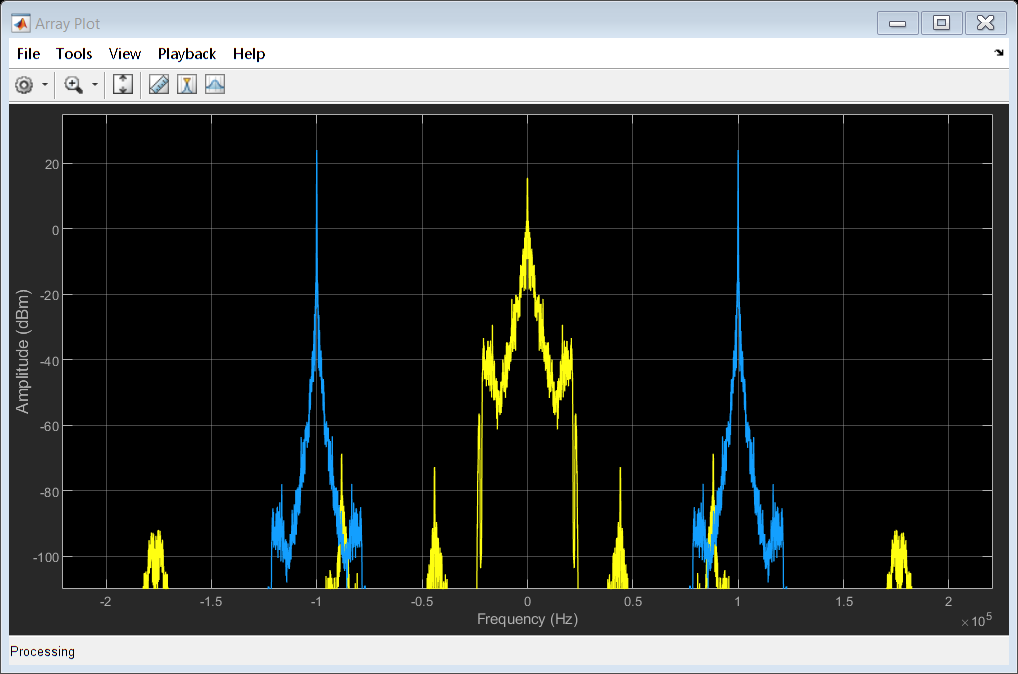

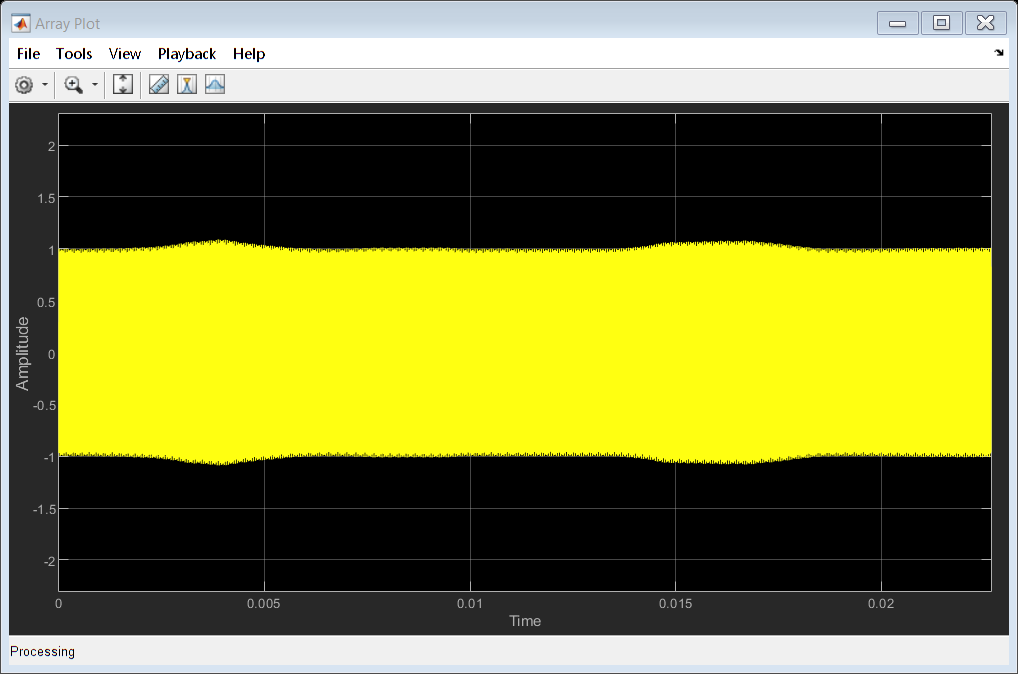

clc; clear; close all;

AudioFrameSize = 1000;      % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 300;         % число обрабатываемых пачек данных
RateRatio = 10;             % коэффициент увеличения частоты дискретизации
Fc = 100e3;                 % частота несущей (Hz)
ModIndex = 0.005;           % индекс модуляции

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% вычисление чувствительности модулятора
Kf = ModIndex * AudioFs / 2;

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate',SignalFs,...
    'SamplesPerFrame',SignalFrameSize,...
    'Frequency', [Fc Fc],...
    'Amplitude', [1 1], ...
    'PhaseOffset', [0 pi/2] ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
PlotterSpectrum = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-110, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

PlotterTime = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/SignalFs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );

% начальное значение интегратора
AccumInitValue = 0;

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % интегрирование сообщения
    MessageIntegral = AccumInitValue + 1/SignalFs * cumsum(MessageData);
    
    % обновление начального значения интегратора
    AccumInitValue = MessageIntegral(end);

    % получание несущей
    CarrierWave = Carrier();
    SinWave = CarrierWave(:,1);
    CosWave = CarrierWave(:,2);

    % умножение на несущую и добавление несущей сдвинутой по фазу
    FmSignal = CosWave - 2*pi*Kf * SinWave.*MessageIntegral; 

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, FmSignal]);

    % вывод результатов на график
    PlotterTime(FmSignal)
    PlotterSpectrum(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

На временной диаграмме можно увидеть появляение побочной амплитудной модуляции. Для борьбы с ней можно попробовать применить рассмотренный ранее способ ограничения и фильтрации. Однако, это будет сопряжено с рядом трудностей. Рассмотрим еще раз сигнал на выходе ограничителя:

$s_{\mathrm{lim}} \left(t\right)=\frac{4}{\pi }\cdot \left(\mathrm{cos}\left(\theta \left(t\right)\right)-\frac{1}{3}\mathrm{cos}\left(3\cdot \theta \left(t\right)\right)+\frac{1}{5}\mathrm{cos}\left(5\cdot \theta \left(t\right)\right)+\ldotp \ldotp \ldotp \right)$,

где $\theta \left(t\right)=2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau$.

Каждое слагаемое в скобках представляет из себя частотно-модулированный сигнал. Нам необходимо только первое слагаемое и его требуется получить отфильтровов все остальные. 

Посмотрим, что представляет из себя второе слагаемое:


$$s_2 \left(t\right)=-\frac{4}{3\pi }\cdot \mathrm{cos}\left(3\cdot \theta \left(t\right)\right)=-\frac{4}{3\pi }\cdot \mathrm{cos}\left(2\pi \left(3\cdot f_с \right)t+2\pi \cdot \left(3\cdot K_f \right)\cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\ldotp$$


Можно увидеть, что $s_2 \left(t\right)$ - это модулированный сигнал, несущая которого равна $3f_с$. Также чувствительность модулятор $3\cdot K_f$ увеличина в трое. Так как, девиация и полоса сигнала пропорцианальны чувствительности, то второе слагаемое будет иметь более широкую полосу, чем первое.

Соответствено, несущая частота и чувствительность третьего лагаемого увеличины в пять раз. Амплитуда слагаемые в сумме $s_{\mathrm{lim}} \left(t\right)$ уменьшается достаточно медленно, поэтому после ограничения мы получим много высокочастотных и широкополосных слагаемых. Так как все преобразования выполняются в цифровом виде, чтобы избежать наложения спектров требуется существенно увеличить частоту дискретизации сигнала. Если этого не сделать, то высокочастотные слагаемые завернуться на частоте Найквиста и попадут в полосу первого слагаемого $\mathrm{cos}\left(\theta \left(t\right)\right)$, после чего их уже не получиться удалить с помощью полосового фильтра.

Сильное увеличение частоты дискретизации тоже не явялется хорошим решением, так как это потребует увеличения числа коэффициентов в полосовом фильтре, и ссответственно увеличит вычислительные затраты.

Таким образом, описанный выше метод узкополосной модуляции можно принять для упрощения передающего устройства, если сигнал формируется аналоговыми методами. Если сигнал формируется цифровыми методами, например с помощью SDR, то лучше использовать прямой метод с малым значение индекса модуляции.

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR